%% LIF neuron demo (Leaky Integrate-and-Fire)
% Simple neuroscience modeling example.
% - Membrane integrates input current and leaks back to rest.
% - When V crosses threshold, emit a spike and reset.
%
% You can convert this script to a Live Script (.mlx) in MATLAB.

clear; close all; clc;

%% 1) Parameters (biophysically-inspired but simplified)
dt      = 0.1;          % time step (ms)
T       = 1000;         % total simulation time (ms)
t       = 0:dt:T;       % time vector
N       = numel(t);

tau_m   = 20;           % membrane time constant (ms)
V_rest  = -65;          % resting potential (mV)
V_reset = -70;          % reset potential after spike (mV)
V_th    = -50;          % spike threshold (mV)

R_m     = 10;           % membrane resistance (MOhm) -> sets how much I changes V
refrac_ms = 2;          % absolute refractory period (ms)
refrac_steps = round(refrac_ms/dt);

%% 2) Input current: baseline + pulses + noise
I_baseline = 1.2;        % nA (try 0.8 to 2.0)
I = I_baseline * ones(1, N);

% Add two current pulses (like a stimulation epoch)
I(t >= 200 & t < 350) = I(t >= 200 & t < 350) + 0.8;
I(t >= 600 & t < 750) = I(t >= 600 & t < 750) + 1.0;

% Add gaussian noise (synaptic background)
noise_sd = 0.25;         % nA
rng(1);                  % reproducible randomness
I = I + noise_sd * randn(1, N);

%% 3) Simulate LIF dynamics
V = zeros(1, N);
V(1) = V_rest;

spike_times = [];        % store spike times (ms)
refrac_counter = 0;      % counts down refractory steps

% Euler integration of: dV/dt = -(V - V_rest)/tau + (R*I)/tau
for k = 2:N
    if refrac_counter > 0
        % During refractory period, clamp to reset
        V(k) = V_reset;
        refrac_counter = refrac_counter - 1;
        continue;
    end

    dV = (-(V(k-1) - V_rest) + R_m * I(k-1)) / tau_m;
    V(k) = V(k-1) + dt * dV;

    if V(k) >= V_th
        % Spike event
        spike_times(end+1) = t(k); %#ok<SAGROW>
        V(k) = V_reset;
        refrac_counter = refrac_steps;
    end
end

%% 4) Simple summary measures
n_spikes = numel(spike_times);
firing_rate_hz = n_spikes / (T/1000);   % spikes per second

fprintf('Total spikes: %d\n', n_spikes);

Total spikes: 10


fprintf('Mean firing rate: %.2f Hz\n', firing_rate_hz);

Mean firing rate: 10.00 Hz



if n_spikes > 1
    isi = diff(spike_times);            % inter-spike intervals (ms)
    fprintf('Mean ISI: %.2f ms\n', mean(isi));
else
    isi = [];
end

Mean ISI: 57.19 ms


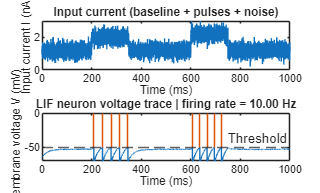


%% 5) Plot: input current + membrane voltage + spike markers
figure;
subplot(2,1,1);
plot(t, I);
xlabel('Time (ms)');
ylabel('Input current I (nA)');
title('Input current (baseline + pulses + noise)');

subplot(2,1,2);
plot(t, V); hold on;
yline(V_th, '--', 'Threshold');
xlabel('Time (ms)');
ylabel('Membrane voltage V (mV)');
title(sprintf('LIF neuron voltage trace | firing rate = %.2f Hz', firing_rate_hz));

% Mark spikes as vertical ticks at threshold level
if ~isempty(spike_times)
    stem(spike_times, V_th * ones(size(spike_times)), 'Marker', 'none');
end

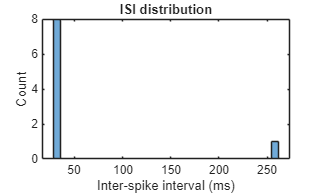


%% 6) Optional: ISI histogram
if ~isempty(isi)
    figure;
    histogram(isi, 30);
    xlabel('Inter-spike interval (ms)');
    ylabel('Count');
    title('ISI distribution');
end